# **Esercitzione n*3 - Stima modelli ingresso uscita**

## Descrizione del problema

E' stato condotto un esperimento per valutare la cinetica del C-peptide (un peptide secreto insieme all'insulina) in 7 soggetti misurando la risposta ad un bolo di C-peptide sintetico. L'esperimento prevede una misura al tempo 0 (prima del bolo) per determinare il valore della concentrazione basale. La misura effettuata al minuto 1 non e' da considerare (e deve essere trascurata nell'identificazione del modello) in quanto ci sono buone ragioni per affermare cha a quel tempo la concentrazione plasmatica non e' uniforme (la sostanza non si e' ancora distribuita nell'intero compartimento plasmatico - problemi di mescolamento). Le misure di concentrazione sono affette da un errore di misura caratterizzato da un CV del 4%. Come esercizio e in via esploratoria, identificare su i dati di almeno un soggetto i modelli a 1,2,3 esponenziali utilizzandp la tecnica dei minimi quadrati e dei minimi quadrati pesati (con peso pari all'inverso della varianza dell'errore di misura). 

clearvars;
clc;

## Lettura dei dati 

I dati sono relativi a 7 soggetti diversi e contenuti nei file` DatiCPSog1.dat`, `DatiCPSog2.dat, ecc.`

% Importazione dei dati 
d_sog1 = importdata("DatiCPsog1.dat");
d_sog2 = importdata("DatiCPsog2.dat");
d_sog3 = importdata("DatiCPsog3.dat");
d_sog4 = importdata("DatiCPsog4.dat");
d_sog5 = importdata("DatiCPsog5.dat");
d_sog6 = importdata("DatiCPsog6.dat");
d_sog7 = importdata("DatiCPsog7.dat");

Dal momento che i dati letti attraverso `importdata `sono organizzati in una struttura che richiederebbe molte operazioni per accedere alle singole informazioni, si memorizzano le informazioni al loro interno in semplici array nel formato che ne permette una corretta manipolazione.

% Data retrieval e data cleaning
dose1 = str2num(d_sog1.textdata{1,2});
t1 = str2num(cell2mat(d_sog1.textdata(4:end,1)));
c1 = str2num(cell2mat(d_sog1.textdata(4:end,2)));

dose2 = str2num(d_sog2.textdata{1,2});
t2 = str2num(cell2mat(d_sog2.textdata(4:end,1)));
c2 = str2num(cell2mat(d_sog2.textdata(4:end,2)));

dose3 = str2num(d_sog3.textdata{1,2});
t3 = str2num(cell2mat(d_sog3.textdata(4:end,1)));
c3 = str2num(cell2mat(d_sog3.textdata(4:end,2)));

dose4 = str2num(d_sog4.textdata{1,2});
t4 = str2num(cell2mat(d_sog4.textdata(4:end,1)));
c4 = str2num(cell2mat(d_sog4.textdata(4:end,2)));

dose5 = str2num(d_sog5.textdata{1,2});
t5 = str2num(cell2mat(d_sog5.textdata(4:end,1)));
c5 = str2num(cell2mat(d_sog5.textdata(4:end,2)));

dose6 = str2num(d_sog6.textdata{1,2});
t6 = str2num(cell2mat(d_sog6.textdata(4:end,1)));
c6 = str2num(cell2mat(d_sog6.textdata(4:end,2)));

dose7 = str2num(d_sog7.textdata{1,2});
t7 = str2num(cell2mat(d_sog7.textdata(4:end,1)));
c7 = str2num(cell2mat(d_sog7.textdata(4:end,2)));


## Analisi visiva

Prima di effettuare il fitting dei possibili modelli a 1,2,3 esponenziali con i minimi quadrati o minimi quadrati pesati, si effettua un'analisi visiva dei dati relativi ai 7 soggetti dello studio.

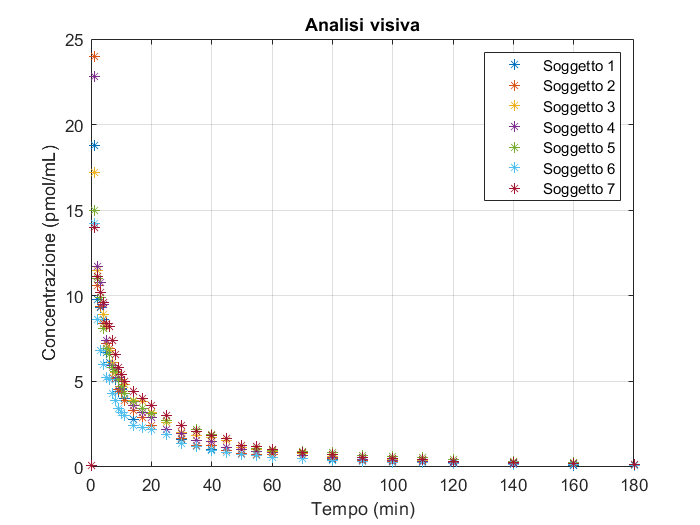

plot(t1,c1,"*",t2,c2,"*",t3,c3,"*",t4,c4,"*",t5,c5,"*",t6,c6,"*",t7,c7,"*"),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title("Analisi visiva"), legend("Soggetto 1","Soggetto 2","Soggetto 3","Soggetto 4", ...
"Soggetto 5","Soggetto 6","Soggetto 7")

## Fitting dei modelli a 1,2,3 esponenziali con il metodo Mimini Quadrati

Prima di effettuare il fitting di qualsiasi modelli e' necessario sottrarre a tutte le misure di concentrazione la concentrazione di C-peptide basale (ottenuta con una misurazione al tempo 0, ovvero prima della somministrazione del bolo di C-peptide sintetico).

c1 = c1 - c1(1);
c2 = c2 - c2(1);
c3 = c3 - c3(1);
c4 = c4 - c4(1);
c5 = c5 - c5(1);
c6 = c6 - c6(1);
c7 = c7 - c7(1);

 E' necessario inoltre eliminare dal fitting le misurazioni effettuate al minuto 1 (anche i vettori dei tempi devono essere modificati).

c1(2) = [];
t1(2) = [];
c2(2) = [];
t2(2) = [];
c3(2) = [];
t3(2) = [];
c4(2) = [];
t4(2) = [];
c5(2) = [];
t5(2) = [];
c6(2) = [];
t6(2) = [];
c7(2) = [];
t7(2) = [];

Il metodo ai Minimi Quadrati consente di trovere i parametri `p` del modello tali che la discrepanza tra i dati `z` e le predezioni del modello `h(ti,p) `sia minima. Per far questo si utilizza il seguente funzionale di costo: 


$$J\left(p\right)=\sum_{i=1}^N {\left(z_i -y_i \right)}^2 =\sum_{i=1}^N {\left(z_i -h\left(t_i \;,p\right)\right)}^2 =\sum_{i=1}^N {e_i }^2$$
 

BIsogna percio' risolvere il seguente problema di ottimizzazione:


$$\hat{p} =\mathrm{argmin}\left(J\left(p\right)\right)$$


In Matlab e' possibile risolverlo tramite la funzione `lsqnonlin`, il cui risultato (i parametri ottimi) sono calcolati utilizzando metodi iterativi. Il funzionale di costo e' definito nell'apposita funzione. Affinche' il metodo iterativo possa cominciare la sua ricerca e' necessario definire un vettori con i parametri iniziali `p0.`

p0 = [18.72,0.7];
[x1_ls,resnorm1_ls,residual1_ls,~,~,~,jacobian1_ls] = lsqnonlin(@funzionale,p0,[],[],[],t1(2:end),c1(2:end),1);


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


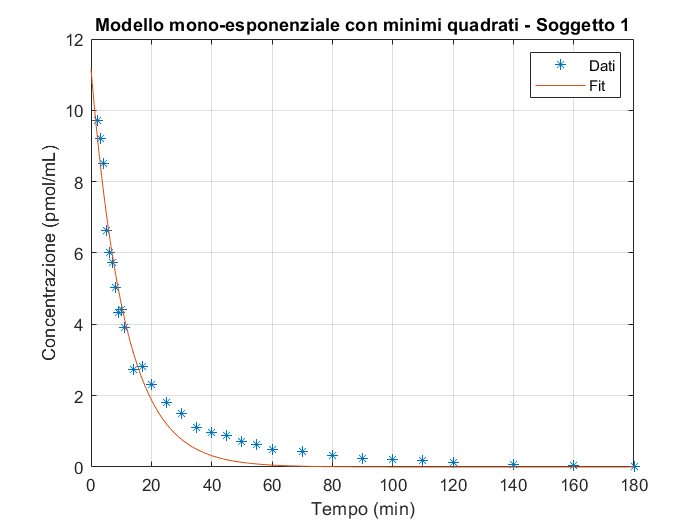

t1_ls = [0:0.001:t1(end)];
plot(t1(2:end),c1(2:end),"*"); hold on, plot(t1_ls,x1_ls(1)*exp(-x1_ls(2)*t1_ls)),
xlabel("Tempo (min)"), ylabel("Concentrazione (pmol/mL)"), grid on,
title("Modello mono-esponenziale con minimi quadrati - Soggetto 1"), legend("Dati","Fit");